clear; close all; clc;

open_system('pt2_dc_machine');

Rload=[10,100,500,1000, 1e5];

for k = 1:length(Rload)
    set_param([bdroot, '/Rload'], 'Resistance', num2str(Rload(k)));
    simOut(k)=sim(gcs);
    disp(['Completed ', num2str(k), ' of ', num2str(length(Rload)), ' simulations'])
end

Completed 1 of 5 simulations
Completed 2 of 5 simulations
Completed 3 of 5 simulations
Completed 4 of 5 simulations
Completed 5 of 5 simulations


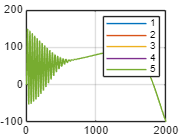


figure;
for k = 1:length(Rload)
    logsout = simOut(k).logsout;
    torque = logsout.getElement('Torque');
    rotor_speed = logsout.getElement('Rotor Speed');
    y_out = torque.Values.Data;
    x_out = rotor_speed.Values.Data;
    plot(x_out, y_out);
    hold on;
end
grid on;
legend('1','2','3','4','5');